# Homework #8

Victoria Subritzky Katz

10/02/2023

## Q1

Plot the relationship between Age and Wing Length.

%data
X = [3,4,5,6,7,8,9,11,12,14,15,16,17];
Y = [1.4,1.5,2.2,2.4,3.1,3.2,3.2,3.9,4.1,4.7,4.5,5.2,5.0];

%plot the data
figure
scatter(X,Y)
xlabel("Age")
ylabel("Wing Length")
title("Relationship of Wing Length to Age")
hold on

## Q2

Calculate and plot the regression line

%linear regression
linear_reg = fitlm(X,Y)

linear_reg = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)    0.82962      0.16774    4.9459    0.00043849
    x1             0.26468     0.015559    17.012    3.0097e-09


Number of observations: 13, Error degrees of freedom: 11
Root Mean Squared Error: 0.256
R-squared: 0.963,  Adjusted R-Squared: 0.96
F-statistic vs. constant model: 289, p-value = 3.01e-09

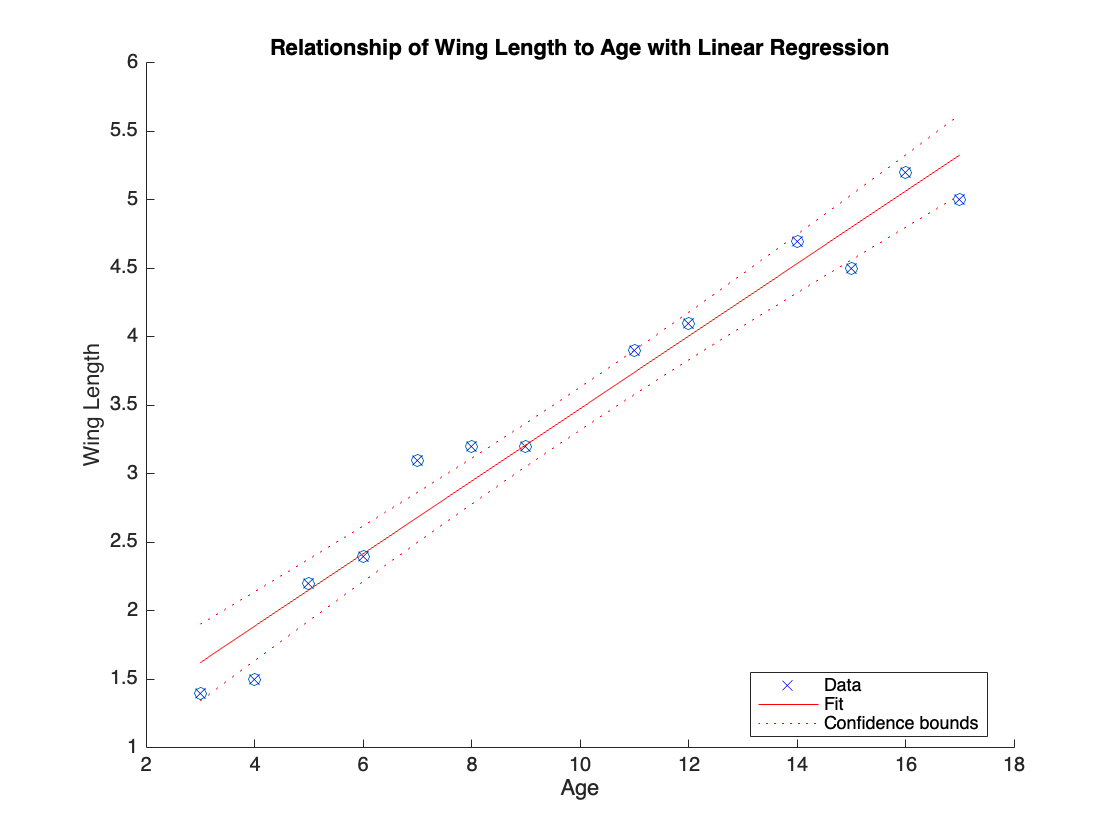

%plot the linear regression onto the data
plot(linear_reg)
hold on
xlabel("Age")
ylabel("Wing Length")
title("Relationship of Wing Length to Age with Linear Regression")

## Q3

Can you reject H0: b=0?

%calculate the f-statistic to determine if we can reject the null
%hypothesis
F_stat = linear_reg.ModelFitVsNullModel.Fstat; 
fprintf("The f-statistic for the null hypothesis of b=0 is %3.2f",F_stat)

The f-statistic for the null hypothesis of b=0 is 289.40

Yes, we can reject the null hypothesis because the f-statistic calculated for the null hypothesis of b=0 is 289.40 is greater than the f critical value for 11 degrees of freedom (n-2) and 1. 

## Q4

Calculate and plot the confidence intervals on the slope of the regression

%already done in question #2


## Q5

Calculate r^2 (the coefficient of determination)

%calculate the coefficient of determination
coefficient_determination = linear_reg.Rsquared.Ordinary;
fprintf("The coefficient of determination is %1.4f",coefficient_determination)

The coefficient of determination is 0.9634

## Q6

Calculate Pearson's *r*

%calculate the Pearson's Coefficient of correlation 
pearsons_r = corrcoef(X,Y);
pearsons_r = pearsons_r(1,2); 
fprintf("The Pearson's coefficient is %1.4f",pearsons_r)

The Pearson's coefficient is 0.9815

## Q7

Add some noise to the data and see how the regression changes.

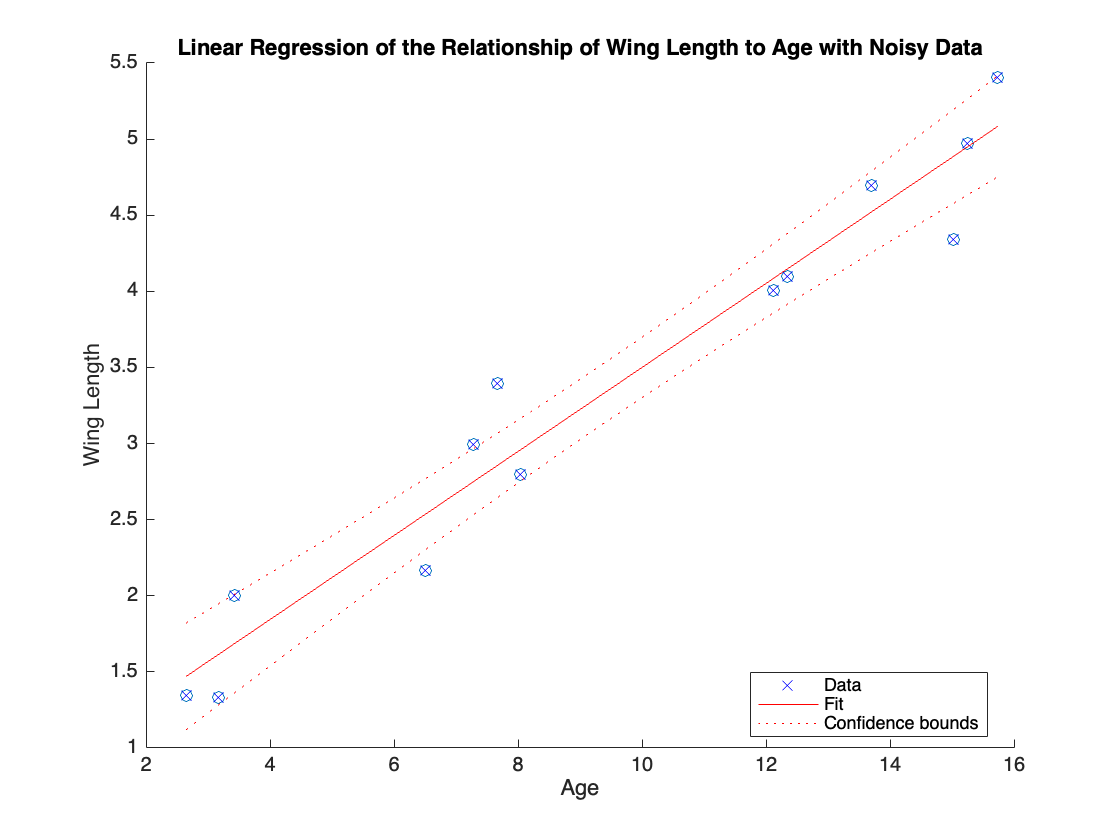

% Define the mean and standard deviation of the Gaussian noise
mean_noise = 0; % Mean of the noise
std_dev_noise_x = 1; % Standard deviation of the noise
std_dev_noise_y = .2; 

% Generate Gaussian noise with the same length as the data
noise_X = normrnd(mean_noise, std_dev_noise_x, size(X));
noise_Y = normrnd(mean_noise, std_dev_noise_y, size(Y));

% Add the noise to the original data
X_noisy = X + noise_X;
Y_noisy = Y + noise_Y;

%linear regression
linear_reg = fitlm(X_noisy,Y_noisy); 

%visualize the data and linear regression
figure
scatter(X_noisy,Y_noisy)
hold on
plot(linear_reg)
hold on
xlabel("Age")
ylabel("Wing Length")
title("Linear Regression of the Relationship of Wing Length to Age with Noisy Data")

The added noise weaked the relationship between the variables, evidenced by the larger confidence intervals for the linear regression.